clear all; close all; clc;

% s0  = [1 0 0];
s0  = [1];
tspan = [0 20];
% k1 = .7;
k1 = .1396;
k2 = .2;
% syms = 
% myeq = 
% [t,s] = ode23(@myfirstode, tspan, s0, [], k1, k2)
[t,s] = ode23(@decayode, tspan, s0, [], k1)

t =          0
    0.5731
    2.5731
    4.5731
    6.5731
    8.5731
   10.5731
   12.5731
   14.5731
   16.5731


s =     1.0000
    0.9231
    0.6980
    0.5278
    0.3991
    0.3018
    0.2282
    0.1725
    0.1305
    0.0987


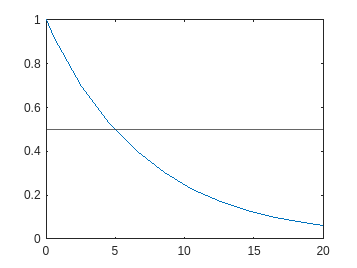

plot(t,s)
yline(.5)

t_halflife = interp1(s, t, .5)

t_halflife = 5.0051

t_halflife

t_halflife = 5.0051

ds = myfirstode(0, [1,2,3], 2, 3)

ds =     -2
    -4
     6


sum(s, 2)

ans =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


s0 = [1 0 0];
k1 = .7;
k2 = .2;
syms A(t) B(t) C(t)

eqns = [
    diff(A, t) == -k1*A
    diff(B,t) == k1*A - k2*B
    diff(C,t)==k2*B
    ]

$$eqns(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}A\left(t\right)=-\frac{7\,A\left(t\right)}{10}\\ \frac{\partial }{\partial t}B\left(t\right)=\frac{7\,A\left(t\right)}{10}-\frac{B\left(t\right)}{5}\\ \frac{\partial }{\partial t}C\left(t\right)=\frac{B\left(t\right)}{5} \end{array}\right)$$

conds = [
    A(0) == s0(1)
    B(0) == s0(2)
    C(0) == s0(3)
    ]

$$conds = \left(\begin{array}{c} A\left(0\right)=1\\ B\left(0\right)=0\\ C\left(0\right)=0 \end{array}\right)$$

S = dsolve()

function ds = decayode(t, s, k)
    A = s(1);
    ds = [-k*A];
end

%%

function ds = myfirstode(t,s,k1,k2);
    %input t the time variable (not used in this case)
    % s the state vector
    % k1,k2 model parameters
    %output ds the derivative ds/dt at time t
    A = s(1); %for clarity & readability, write the
    B = s(2); %model using the notation A,B,C for the
    C = s(3); %components
    dA = -k1*A; %the ODE system equations
    dB = k1*A - k2*B;
    dC = k2*B;
    ds = [dA;dB;dC]; %collect the output in vector ds
end